clc; clear all; close all;
addpath(genpath('.\shared'))

global   thvalues  ratio L; 
global   im_tag sensor;
global   file_path_rgb_noR; 
global  count time num ;
global  sate curr_d coll_flag;

curr_d = pwd;

sate = 'ik';   % geo,ik,pl, qb, wv2，wv3

coll_flag = 0;
method = 'lu7';


## start initialization


initialize_sate_FS();


## start process


 for  num= 1:60
     count = 1 + count
     
    %% read images and preprocess, need to change here###########    
    [mul_noR, pan_noR ] = read_image_sate_FS(num);
    
    %% tic start
    tic()   
    
    img_mul = im2double(mul_noR);
    P = im2double(pan_noR);    

count = 1

count = 2

count = 3

count = 4

count = 5

count = 6

count = 7

count = 8

count = 9

count = 10

count = 11

count = 12

count = 13

count = 14

count = 15

count = 16

count = 17

count = 18

count = 19

count = 20

count = 21

count = 22

count = 23

count = 24

count = 25

count = 26

count = 27

count = 28

count = 29

count = 30

count = 31

count = 32

count = 33

count = 34

count = 35

count = 36

count = 37

count = 38

count = 39

count = 40

count = 41

count = 42

count = 43

count = 44

count = 45

count = 46

count = 47

count = 48

count = 49

count = 50

count = 51

count = 52

count = 53

count = 54

count = 55

count = 56

count = 57

count = 58

count = 59

count = 60

## initial

    [m,n] = size(P);
    M =imresize(img_mul,size(P),'bicubic');   % 双三次插值算法
    
    [I,alpha] = get_I(sate,M, P);


    I_ori = zeros(size(img_mul,1), size(img_mul,2));
    for i= 1:size(M,3)
        I_ori = I_ori + alpha(i)*img_mul(:,:,i);
    end

## original

    M_sum = zeros(size(M,1),size(M,2));
    for i = 1:size(M,3)
        M_sum = M_sum + M(:,:,i);
    end
    M_sum(find(M_sum==0))=eps;
    
    M_rate = zeros(size(M));
    for i=1:size(M,3)
        M_rate(:,:,i) = size(M,3)*M(:,:,i)./M_sum;
    end

    [H,sig,cor_old, P_L] = get_gau_H_RS(P, I);    
    
    switch sate
        case 'ik'
            g = 0.8;

        case 'pl'
            g = 0.91;

        case 'wv3-8'
            g = 1.4;

        case 'qb'
            g = 1;

        case 'geo'
            g = 1.6;

    end


    IH3_new = get_IH_org_FS(P, I, I_ori);

iter = 2

iter = 3

iter = 4

iter = 5

iter = 6

iter = 7

iter = 8

iter = 9

iter = 10

iter = 2

iter = 3

iter = 4

iter = 5

iter = 6

iter = 7

iter = 8

iter = 9

iter = 10

iter = 2

iter = 3

iter = 4

iter = 5

iter = 6

iter = 7

iter = 8

iter = 9

iter = 10

iter = 11

iter = 12

iter = 13

iter = 14

iter = 15

iter = 16

iter = 17

iter = 18

iter = 19

iter = 20

iter = 2

iter = 3

iter = 4

iter = 5

iter = 6

iter = 7

iter = 8

iter = 9

iter = 10

iter = 2

iter = 3

iter = 4

iter = 5

iter = 6

iter = 7

iter = 8

iter = 9

iter = 10

iter = 2

iter = 3

iter = 4

iter = 5

iter = 6

iter = 7

iter = 8

iter = 9

iter = 10

iter = 2

iter = 3

iter = 4

iter = 5

iter = 6

iter = 7

iter = 8

iter = 9

iter = 10

iter = 2

iter = 3

iter = 4

iter = 5

iter = 6

iter = 7

iter = 8

iter = 9

iter = 10

iter = 2

iter = 3

iter = 4

iter = 5

iter = 6

iter = 7

iter = 8

iter = 9

iter = 10

iter = 2

iter = 3

iter = 4

iter = 5

iter = 6

iter = 7

iter = 8

iter = 9

iter = 10

iter = 11

iter = 12

iter = 13

iter = 14

iter = 15

iter = 2

iter = 3

iter = 4

iter = 5

iter = 6

iter = 7

iter = 8

iter = 9

iter = 10

iter = 2

iter = 3

iter = 4

iter = 5

iter = 6

iter = 7

iter = 8

iter = 9

iter = 10

iter = 2

iter = 3

iter = 4

iter = 5

iter = 6

iter = 7

iter = 8

iter = 9

iter = 10

iter = 2

iter = 3

iter = 4

iter = 5

iter = 6

iter = 7

iter = 8

iter = 9

iter = 10

iter = 2

iter = 3

iter = 4

iter = 5

iter = 6

iter = 7

iter = 8

iter = 9

iter = 10

iter = 2

iter = 3

iter = 4

iter = 5

iter = 6

iter = 7

iter = 8

iter = 9

iter = 10

iter = 2

iter = 3

iter = 4

iter = 5

iter = 6

iter = 7

iter = 8

iter = 9

iter = 10

iter = 2

iter = 3

iter = 4

iter = 5

iter = 6

iter = 7

iter = 8

iter = 9

iter = 10

iter = 2

iter = 3

iter = 4

iter = 5

iter = 6

iter = 7

iter = 8

iter = 9

iter = 10

iter = 2

iter = 3

iter = 4

iter = 5

iter = 6

iter = 7

iter = 8

iter = 9

iter = 10

iter = 2

iter = 3

iter = 4

iter = 5

iter = 6

iter = 7

iter = 8

iter = 9

iter = 10

iter = 2

iter = 3

iter = 4

iter = 5

iter = 6

iter = 7

iter = 8

iter = 9

iter = 10

iter = 2

iter = 3

iter = 4

iter = 5

iter = 6

iter = 7

iter = 8

iter = 9

iter = 10

iter = 2

iter = 3

iter = 4

iter = 5

iter = 6

iter = 7

iter = 8

iter = 9

iter = 10

iter = 2

iter = 3

iter = 4

iter = 5

iter = 6

iter = 7

iter = 8

iter = 9

iter = 10

iter = 2

iter = 3

iter = 4

iter = 5

iter = 6

iter = 7

iter = 8

iter = 9

iter = 10

iter = 11

iter = 12

iter = 13

iter = 14

iter = 15

iter = 2

iter = 3

iter = 4

iter = 5

iter = 6

iter = 7

iter = 8

iter = 9

iter = 10

iter = 2

iter = 3

iter = 4

iter = 5

iter = 6

iter = 7

iter = 8

iter = 9

iter = 10

iter = 2

iter = 3

iter = 4

iter = 5

iter = 6

iter = 7

iter = 8

iter = 9

iter = 10

iter = 2

iter = 3

iter = 4

iter = 5

iter = 6

iter = 7

iter = 8

iter = 9

iter = 10

iter = 2

iter = 3

iter = 4

iter = 5

iter = 6

iter = 7

iter = 8

iter = 9

iter = 10

iter = 2

iter = 3

iter = 4

iter = 5

iter = 6

iter = 7

iter = 8

iter = 9

iter = 10

iter = 11

iter = 12

iter = 13

iter = 14

iter = 15

iter = 2

iter = 3

iter = 4

iter = 5

iter = 6

iter = 7

iter = 8

iter = 9

iter = 10

iter = 2

iter = 3

iter = 4

iter = 5

iter = 6

iter = 7

iter = 8

iter = 9

iter = 10

iter = 2

iter = 3

iter = 4

iter = 5

iter = 6

iter = 7

iter = 8

iter = 9

iter = 10

iter = 2

iter = 3

iter = 4

iter = 5

iter = 6

iter = 7

iter = 8

iter = 9

iter = 10

iter = 11

iter = 12

iter = 13

iter = 14

iter = 15

iter = 16

iter = 17

iter = 18

iter = 2

iter = 3

iter = 4

iter = 5

iter = 6

iter = 7

iter = 8

iter = 9

iter = 10

iter = 2

iter = 3

iter = 4

iter = 5

iter = 6

iter = 7

iter = 8

iter = 9

iter = 10

iter = 11

iter = 12

iter = 13

iter = 14

iter = 15

iter = 16

iter = 2

iter = 3

iter = 4

iter = 5

iter = 6

iter = 7

iter = 8

iter = 9

iter = 10

iter = 11

iter = 12

iter = 13

iter = 14

iter = 15

iter = 16

iter = 17

iter = 18

iter = 19

iter = 20

iter = 21

iter = 22

iter = 23

iter = 24

iter = 2

iter = 3

iter = 4

iter = 5

iter = 6

iter = 7

iter = 8

iter = 9

iter = 10

iter = 11

iter = 12

iter = 13

iter = 14

iter = 15

iter = 16

iter = 2

iter = 3

iter = 4

iter = 5

iter = 6

iter = 7

iter = 8

iter = 9

iter = 10

iter = 2

iter = 3

iter = 4

iter = 5

iter = 6

iter = 7

iter = 8

iter = 9

iter = 10

iter = 11

iter = 2

iter = 3

iter = 4

iter = 5

iter = 6

iter = 7

iter = 8

iter = 9

iter = 10

iter = 2

iter = 3

iter = 4

iter = 5

iter = 6

iter = 7

iter = 8

iter = 9

iter = 10

iter = 11

iter = 12

iter = 13

iter = 14

iter = 15

iter = 2

iter = 3

iter = 4

iter = 5

iter = 6

iter = 7

iter = 8

iter = 9

iter = 10

iter = 2

iter = 3

iter = 4

iter = 5

iter = 6

iter = 7

iter = 8

iter = 9

iter = 10

iter = 11

iter = 12

iter = 13

iter = 14

iter = 2

iter = 3

iter = 4

iter = 5

iter = 6

iter = 7

iter = 8

iter = 9

iter = 10

iter = 2

iter = 3

iter = 4

iter = 5

iter = 6

iter = 7

iter = 8

iter = 9

iter = 10

iter = 2

iter = 3

iter = 4

iter = 5

iter = 6

iter = 7

iter = 8

iter = 9

iter = 10

iter = 2

iter = 3

iter = 4

iter = 5

iter = 6

iter = 7

iter = 8

iter = 9

iter = 10

iter = 2

iter = 3

iter = 4

iter = 5

iter = 6

iter = 7

iter = 8

iter = 9

iter = 10

iter = 2

iter = 3

iter = 4

iter = 5

iter = 6

iter = 7

iter = 8

iter = 9

iter = 10

iter = 11

iter = 12

iter = 13

iter = 14

iter = 2

iter = 3

iter = 4

iter = 5

iter = 6

iter = 7

iter = 8

iter = 9

iter = 10

iter = 2

iter = 3

iter = 4

iter = 5

iter = 6

iter = 7

iter = 8

iter = 9

iter = 10

iter = 2

iter = 3

iter = 4

iter = 5

iter = 6

iter = 7

iter = 8

iter = 9

iter = 10

iter = 2

iter = 3

iter = 4

iter = 5

iter = 6

iter = 7

iter = 8

iter = 9

iter = 10

iter = 2

iter = 3

iter = 4

iter = 5

iter = 6

iter = 7

iter = 8

iter = 9

iter = 10

iter = 2

iter = 3

iter = 4

iter = 5

iter = 6

iter = 7

iter = 8

iter = 9

iter = 10

iter = 2

iter = 3

iter = 4

iter = 5

iter = 6

iter = 7

iter = 8

iter = 9

iter = 10

iter = 2

iter = 3

iter = 4

iter = 5

iter = 6

iter = 7

iter = 8

iter = 9

iter = 10


    H2 = get_H_MTF_M(M,sensor,[],ratio);
    
    D_In = IH3_new - I;

    co2 = corr2(IH3_new,I);
    coef = (1/(co2-0.05)^2);
    if (strcmp(sate, 'wv3-8'))
        coef1 =  sigmf((co2),[1 -0.7]);
        coef2 =  sigmf((1-co2),[1 0.8]);
    end
    if (strcmp(sate, 'pl'))
        coef1 =  sigmf((co2),[1 -0.9]);
        coef2 =  sigmf((1-co2),[1 -0.2]);
    end
    if (strcmp(sate, 'ik'))
        coef1 =  sigmf((co2),[1 -0.4]);
        coef2 =  sigmf((1-co2),[1 0]);
    end    

    for i = 1 : size(M,3)
        ML(:,:,i) = ifft2(fft2(M(:,:,i)).*H2(:,:,i));
        D_m(:,:,i) = M(:,:,i) - ML(:,:,i);
        t(i) = mean2(abs(D_In))/mean2(abs(D_m(:,:,i)));        
        alpha3(i) = estimation_alpha(abs(D_m(:,:,i)),abs(D_In),'global');

        
        D_t1(:,:,i) = alpha3(i) * D_m(:,:,i);
        D_t2(:,:,i) = t(i) * D_m(:,:,i);

        co = co2;
        D_new(:,:,i) =  coef1 * D_In + coef2* D_t1(:,:,i);

    end
    
    g1 = ones(1,size(M,3));
    for ii = 1 : size(M,3)
        h = M(:,:,ii);
        c = cov(I(:),h(:));
        g1(1, ii) = abs( c(1,2)/var(I(:)));
    end

## get final image

    F_final = zeros(size(M));

    for i = 1:size(M,3)
        F_final(:,:,i) = M(:,:,i)+ g * M_rate(:,:,i).*D_new(:,:,i);
    end
    
    toc

历时 6.519993 秒。


历时 6.145265 秒。


历时 10.451378 秒。


历时 6.208942 秒。


历时 6.166831 秒。


历时 6.060454 秒。


历时 6.072594 秒。


历时 6.278859 秒。


历时 6.286903 秒。


历时 8.175250 秒。


历时 6.047392 秒。


历时 6.785324 秒。


历时 5.963360 秒。


历时 6.049789 秒。


历时 6.060072 秒。


历时 6.086643 秒。


历时 5.967586 秒。


历时 5.976230 秒。


历时 5.947176 秒。


历时 5.953217 秒。


历时 5.914058 秒。


历时 6.032971 秒。


历时 6.007835 秒。


历时 5.950720 秒。


历时 5.981063 秒。


历时 7.898457 秒。


历时 5.916205 秒。


历时 5.930947 秒。


历时 5.984390 秒。


历时 5.889099 秒。


历时 5.820341 秒。


历时 8.036038 秒。


历时 6.039204 秒。


历时 6.035238 秒。


历时 5.961130 秒。


历时 9.172224 秒。


历时 6.185286 秒。


历时 8.292542 秒。


历时 11.327856 秒。


历时 8.300360 秒。


历时 5.985222 秒。


历时 6.301282 秒。


历时 5.890445 秒。


历时 8.062034 秒。


历时 6.120552 秒。


历时 7.655938 秒。


历时 6.914722 秒。


历时 5.984057 秒。


历时 5.965501 秒。


历时 5.966225 秒。


历时 6.076787 秒。


历时 7.640641 秒。


历时 5.982704 秒。


历时 5.930839 秒。


历时 5.922175 秒。


历时 5.943791 秒。


历时 5.967283 秒。


历时 5.970628 秒。


历时 5.878603 秒。


历时 5.876859 秒。


    time(num) = toc;

## show RGB

    F_rgb = zeros(m,n,3);
    for i = 1:3
        F_rgb(:,:,i) =  F_final(:,:,i);
    end
    cd(curr_d);
   
    % ############## save image here, need to change the path ##################
 save_sate_FS(F_final, M, F_rgb, num);
 end 
 

## show image

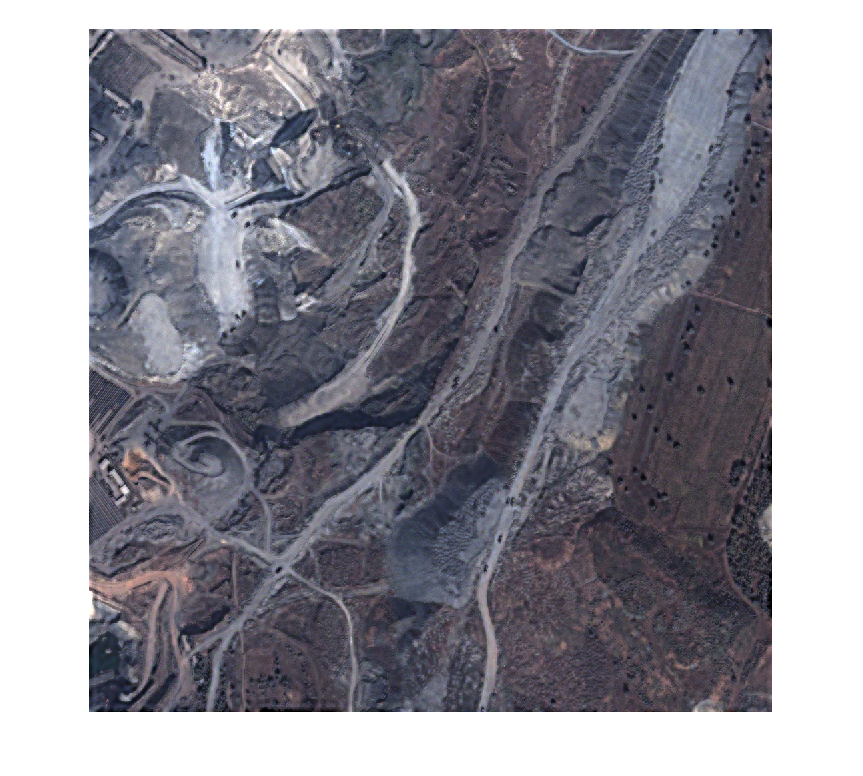


figure, imshow(F_rgb);

[Dl,Ds,QNR_index,SAM_index,sCC] = indexes_evaluation_FS(F_final,img_mul,P,...
    L,thvalues,M,sensor,im_tag,ratio);
Eval = [Dl,Ds,QNR_index]

Eval =     0.0773    0.0709    0.8573


cd(curr_d);


## write result

T = quality_eval_sate_FS();

eval_times = 1

eval_times = 2

eval_times = 3

eval_times = 4

eval_times = 5

eval_times = 6

eval_times = 7

eval_times = 8

eval_times = 9

eval_times = 10

eval_times = 11

eval_times = 12

eval_times = 13

eval_times = 14

eval_times = 15

eval_times = 16

eval_times = 17

eval_times = 18

eval_times = 19

eval_times = 20

eval_times = 21

eval_times = 22

eval_times = 23

eval_times = 24

eval_times = 25

eval_times = 26

eval_times = 27

eval_times = 28

eval_times = 29

eval_times = 30

eval_times = 31

eval_times = 32

eval_times = 33

eval_times = 34

eval_times = 35

eval_times = 36

eval_times = 37

eval_times = 38

eval_times = 39

eval_times = 40

eval_times = 41

eval_times = 42

eval_times = 43

eval_times = 44

eval_times = 45

eval_times = 46

eval_times = 47

eval_times = 48

eval_times = 49

eval_times = 50

eval_times = 51

eval_times = 52

eval_times = 53

eval_times = 54

eval_times = 55

eval_times = 56

eval_times = 57

eval_times = 58

eval_times = 59

eval_times = 60

cd(curr_d);
writetable(T,strcat('final_result/quality_',method,'_4C_',sate,'_FS3.xlsx'),'WriteRowNames',true);